# Radar Target Classification Using Machine Learning and Deep Learning

Target classification is an important function in modern radar systems. This example uses machine classify radar echoes from a cylinder and a cone.** Although this example uses the synthesized I/Q samples, the workflow is applicable to real radar returns**.

% Start Fresh
clear
close all

## Load and Visualize RADAR Data

The return of the cone can be generated similarly. To create the training set, the above process is repeated for 5 arbitrarily selected cylinder radii. In addition, for each radius, 10 motion profiles are simulated by varying the incident angle following 10 randomly generated sinusoid curve around boresight. There are 701 samples in each motion profile, so there are 701-by-50 samples. The process is repeated for the cylinder target, which results in a 701-by-100 matrix of training data with 50 cylinder and 50 cone profiles. In the test set, we use 25 cylinder and 25 cone profiles to create a 701-by-50 training set. Because of the long computation time, the training data is precomputed and loaded below.

### Load Data

load('RCSClassificationReturnsTraining');
load('RCSClassificationReturnsTest');

### Plot Data

As an example, the next plot shows the return for one of the motion profiles from each shape. The plots show how the values change over time for both the incident azimuth angles and the target returns.

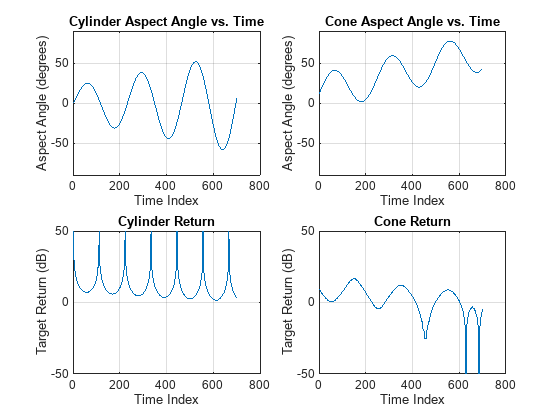

helperPlotRCS(cylinderAspectAngle,RCSReturns, coneAspectAngle)

## Wavelet Scattering

In the wavelet scattering feature extractor, data is propagated through a series of wavelet transforms, nonlinearities, and averaging to produce low-variance representations of time series. Wavelet time scattering yields signal representations insensitive to shifts in the input signal without sacrificing class discriminability. 

The key parameters to specify in a wavelet time scattering network are the scale of the time invariant, the number of wavelet transforms, and the number of wavelets per octave in each of the wavelet filter banks. In many applications, the cascade of two filter banks is sufficient to achieve good performance. In this example, we construct a wavelet time scattering network with the two filter banks: 4 wavelets per octave in the first filter bank and 2 wavelets per octave in the second filter bank. The invariance scale is set to 701 samples, the length of the data.

sn = waveletScattering('SignalLength',701,'InvarianceScale',701,'QualityFactors',[4 2]);

Next, we obtain the scattering transforms of both the training and test sets.

sTrain = sn.featureMatrix(RCSReturns{:,:},'transform','log');
sTest = sn.featureMatrix(RCSReturnsTest{:,:},'transform','log');

For this example, use the mean of the scattering coefficients taken along each path.

TrainFeatures = squeeze(mean(sTrain,2))';
TestFeatures = squeeze(mean(sTest,2))';

Create the labels for training and learning

TrainLabels = repelem(categorical({'Cylinder','Cone'}),[50 50])';
TestLabels = repelem(categorical({'Cylinder','Cone'}),[25 25])';

## Model Training

Fit a support vector machine model with a quadratic kernel to the scattering features and obtain the cross-validation accuracy.

template = templateSVM('KernelFunction', 'polynomial', ...
    'PolynomialOrder', 2, ...
    'KernelScale', 'auto', ...
    'BoxConstraint', 1, ...
    'Standardize', true);

classificationSVM = fitcecoc(...
    TrainFeatures, ...
    TrainLabels, ...
    'Learners', template, ...
    'Coding', 'onevsone', ...
    'ClassNames', categorical({'Cylinder','Cone'}));

partitionedModel = crossval(classificationSVM, 'KFold', 5);
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);
validationAccuracy = (1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError'))*100

validationAccuracy = 100

## Target Class Prediction

Using the trained SVM, classify the scattering features obtained from the test set.

predLabels = predict(classificationSVM,TestFeatures);
accuracy = sum(predLabels == TestLabels )/numel(TestLabels)*100

accuracy = 100

Plot the confusion matrix.

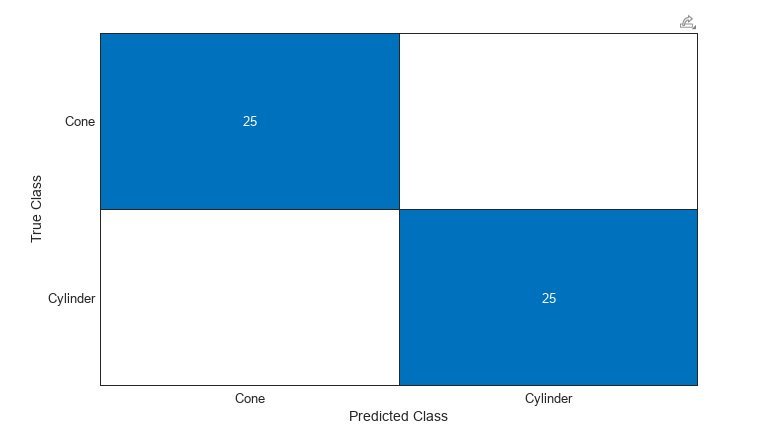

figure('Units','normalized','Position',[0.2 0.2 0.5 0.5]);
confusionchart(TestLabels,predLabels);

## Classification Learner App

Try other Machine Learning Models, this time using [**Classification Learner App**](matlab:open('C:\Program Files\MATLAB\R2022b\help\stats\classificationlearner-app.html')).

**Supporting Functions**

function helperPlotRCS(cylinderAspectAngle,RCSReturns, coneAspectAngle)
    subplot(2,2,1)
    plot(cylinderAspectAngle(1,:))
    ylim([-90 90])
    grid on
    title('Cylinder Aspect Angle vs. Time'); xlabel('Time Index'); ylabel('Aspect Angle (degrees)');
    subplot(2,2,3)
    plot(RCSReturns.Cylinder_1); ylim([-50 50]);
    grid on
    title('Cylinder Return'); xlabel('Time Index'); ylabel('Target Return (dB)');
    subplot(2,2,2)
    plot(coneAspectAngle(1,:)); ylim([-90 90]); grid on;
    title('Cone Aspect Angle vs. Time'); xlabel('Time Index'); ylabel('Aspect Angle (degrees)');
    subplot(2,2,4);
    plot(RCSReturns.Cone_1); ylim([-50 50]); grid on;
    title('Cone Return'); xlabel('Time Index'); ylabel('Target Return (dB)');
end